% Main File to generate combined Calcium Transient Figure for all models
close all; clear; clc;

% Load initial conditions and the original baseline parameters
load ICs_baseline;
load baseline_parameter_inputs;

baseline_parameter_inputs(87) = 0.003 %0.0026

baseline_parameter_inputs = 1.0e+04 *

    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001




% Store a clean copy of the baseline parameters to reset before each simulation
original_baseline_params = baseline_parameter_inputs;

% ========================================================================
%  START: BATCH SIMULATION BLOCK
% ========================================================================

num_models = 5; % We are running 5 simulations: Baseline (0) + 4 Models
% Use cell arrays to store the results from each simulation
all_ca_beats = cell(1, num_models);
all_time_beats = cell(1, num_models);
model_legends = cell(1, num_models);

% --- Loop through each model from 0 (Baseline) to 4 ---
for model_id = 0:(num_models - 1)

    % --- 2. Define Parameter Indices (as in your original code) ---
    g_Kr_index = 2;   % Conductance of IKr
    g_Na_index = 7;  % Conductance of INa (proxy for late current)
    p_CaL_index = 5; % Permeability of ICaL (proxy for persistent current)
    g_K1_index = 1;   % Conductance of IK1 (Added for stabilization)
    C_persist_CaL_index = 86; % Our new persistent ICaL parameter
    C_persist_NaL_index = 87; % Persistent INaL parameter (tuned to hit 0.0026 experimentally accurate ratio)
    fprintf('Running simulation for Model ID: %d\n', model_id);

    % --- 1. Reset parameters to the original baseline for each iteration ---
    modified_params = original_baseline_params;
    modified_params(83) = 1; % Off = 0 | ON = 1 |% This is the master "on/off" switch for pacing.

        % This is what we will scale by 2.29-fold OR 2.31-fold
    baseline_C_persist_CaL = modified_params(C_persist_CaL_index);
    baseline_C_persist_NaL = modified_params(C_persist_NaL_index);

        modified_params(g_K1_index) = modified_params(g_K1_index) * 5; % Kernik-Clancy Mature iPSC-CM
        modified_params(g_Na_index) = modified_params(g_Na_index) * 1.45; % Kernik-Clancy Mature iPSC-CM



    % --- 3. Apply Modifications Based on the current model_id ---
    if model_id == 0
        plot_title = 'Baseline (Isogenic Control)';
        % No parameter changes needed for the baseline model
    elseif model_id == 1
        plot_title = 'Model 1: IKr Defect Only';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    elseif model_id == 2
        plot_title = 'Model 2: IKr + INa,L';
        % Apply IKr reduction
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        % Apply 2.31-fold INa,L increase
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31*3;
    elseif model_id == 3
        plot_title = 'Model 3: IKr + ICa,L';
        % Apply IKr reduction
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        % Apply 2.29-fold ICa,L increase (from your previous query)
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    elseif model_id == 4
        plot_title = 'Model 4: All Three Defects';
        % Apply all three modifications   
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31*3;
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    end
    model_legends{model_id + 1} = plot_title;

    % --- 4. Run the ODE simulation for the current model ---
    options = odeset('MaxStep',1,'InitialStep',2e-2);
    run_time=6e3; %originally 3e3
    [Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, modified_params);
    Cai = values(:,3);

    % --- 5. Extract the single beat for analysis (logic from ca_analysis.m) ---
    % This logic finds the start and end of the second beat
    inds_time_1200 = find(Time > 1200, 1, 'first');
    inds_time_2400 = find(Time > 2400, 1, 'first'); %original: inds1=1200, ind2=2400  | now 4500
    [~, inds1] = min(Cai(1:inds_time_1200));
    [~, temp_inds2] = min(Cai(inds_time_1200:inds_time_2400));
    inds2 = inds_time_1200 + temp_inds2 - 1; % Adjust index to be global

    ca_beat = Cai(inds1:inds2);
    time_beat = Time(inds1:inds2);

    % --- 6. Store the results for the combined plot ---
    % Normalize time so all beats start at t=0 and convert to seconds
    all_time_beats{model_id + 1} = (time_beat - time_beat(1)) / 1000;
    % Convert Calcium concentration to nM
    all_ca_beats{model_id + 1} = ca_beat * 1e6;

end % --- End of simulation loop ---

Running simulation for Model ID: 0
Running simulation for Model ID: 1
Running simulation for Model ID: 2
Running simulation for Model ID: 3
Running simulation for Model ID: 4



% ========================================================================
%  START: COMBINED PLOTTING BLOCK (Replaces Figure 10A plot)
% ========================================================================

fprintf('Simulations complete. Generating combined plot...\n');

Simulations complete. Generating combined plot...


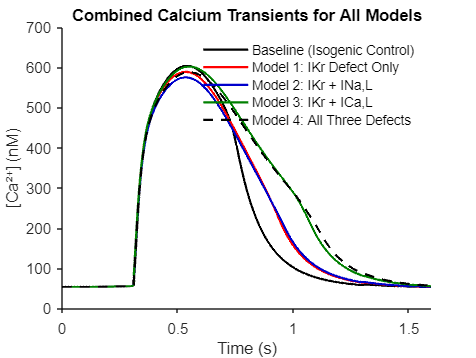


figure;
set(gcf, 'color', 'w');
hold on; % This is crucial for overlaying plots

% --- Define a set of colors for better visualization ---
colors = [0 0 0;                      % Black for Baseline
          1 0 0;                      % Red for Model 1
          0 0 0.8;                    % Dark blue for Model 2
          0 0.5 0;                    % Green for Model 3
          0 0 0];                     % MODIFIED: Black for Model 4

% --- Loop through the stored results and plot each one on the same axes ---
for i = 1:num_models
    % --- MODIFICATION START ---
    if i == 5 % Check if it's the 5th model (your "Model 4")
        % Plot Model 4 as a dashed black line
        plot(all_time_beats{i}, all_ca_beats{i}, 'Color', colors(i,:), 'LineStyle', '--', 'LineWidth', 1.5);
    else
        % Plot all other models as solid lines
        plot(all_time_beats{i}, all_ca_beats{i}, 'Color', colors(i,:), 'LineWidth', 1.5);
    end
    % --- MODIFICATION END ---
end

hold off; % Release the figure hold

% --- Add labels, title, and legend ---
title('Combined Calcium Transients for All Models');
xlabel('Time (s)');
ylabel('[Ca²⁺] (nM)'); % Using Unicode for superscript
legend(model_legends, 'Location', 'northeast');
legend boxoff;
set(gca, 'box', 'off', 'tickdir', 'out');


fprintf('Combined plot generated successfully.\n');

Combined plot generated successfully.



% NOTE: The rest of your script (data table calculations, AP analysis, etc.)
% will currently only work on the data from the *last* simulation (Model 4).
% To analyze all models, you would need to store the 'ca_results' and
% 'Vm' from each loop iteration, similar to how the calcium beats were stored.